# Training set generation for Deep Learning

#### [220404] training_set_gen_v1 : (Kolmogorov 3to8) Feature intensity generation (10000 training set)

#### **[220404] training_set_gen_v1_modes : (Kolmogorov 3toN) Feature intensity generation (10000 training set)**

#### **[220404] training_set_gen_v1_gradient : (Kolmogorov 3to14) Feature intensity & gradient generation (10000 training set)**

#### [220502] training_set_gen_v4 : (random) Feature intensity generation (10000 training set)

#### [220504] training_set_gen_v5 : (random) zernike mode sequential update (3,4,5,6,7,8,34,345,3456,34567,345678)

#### [220506] training_set_gen_v6 : (Kolmogorov) zernike mode sequential update (3,4,5,6,7,8,34,345,3456,34567,345678)

## Sensorless adaptive optics system overview

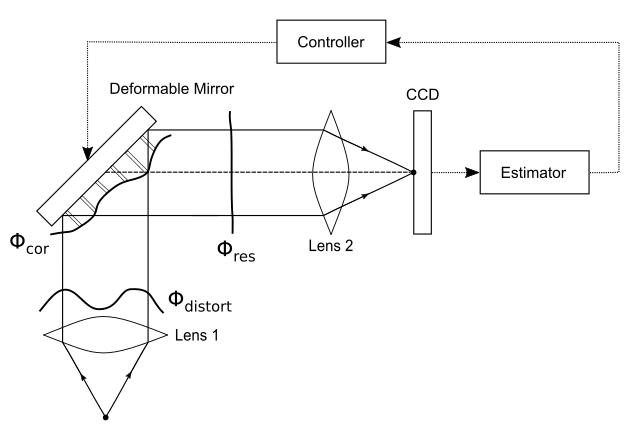

## The order of Zernike modes follow the OSA/ANSI standard indices

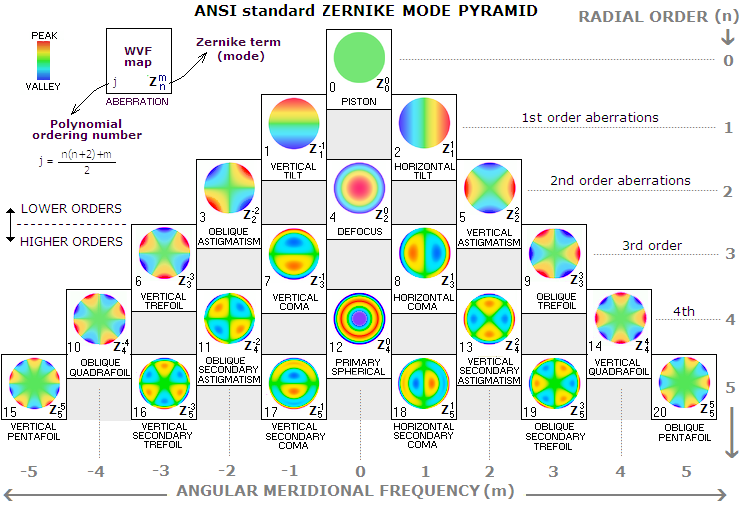

## Generating time-varying phase aberrations by OOMAO Toolbox

The time-varying phase aberration caused by atmospheric turbulence is generated by **Object-Oriented MATLAB & Adaptive Optics (OOMAO) Toolbox** [[2]].

The OOMAO sources are hosted by GitHub (https://github.com/rconan/OOMAO).

To illustrate a complex environment such as the real-world atmosphere, we designed a *mainly frozen-flow model* with three layers at diferent heights, wind speeds, and directions [[3]].

### Main parameter

1. r0 : 수차 크기를 조절 (D는 고정)

2. nSimSteps : 생성하려는 파면 수차의 개수를 설정

3. len : 파면의 pixel size를 의미 → len = 64일 경우, 64 x 64 이미지 파면 생성

4. samplingFreq : 파면 변화 속도를 결정 (samplingFreq가 작을수록 더 빠르게 변화)

clear;clc;close all;

 @(logBook)> Closing the log book!
~~~~~~~~~~~~~~~~~~~
 OOMAO'S GONE!
~~~~~~~~~~~~~~~~~~~


cwd = pwd;             % check the current folder
addpath(genpath(cwd)); % add subfolers

samplingFreq = 200; % turbulence sampling frequency
T_s_tur = 1/samplingFreq; % turbulence sampling time
nSimSteps = 1e+5; % total number of phase screen

D = 1; % telescope diameter [m]
r0 = 0.2; % Fried parameter [m] % The strength of atmospheric turbulence (D/r0) is set as 5.
L0 = 42; % outer scale [m]

% mainly frozen-flow model
h = [1000, 5000, 12000]; % height [m]
v0 = [5, 7.5, 10]; % wind speed [m/s]
vD = [0, pi/3, 5*pi/3]; % wind direction
f_r0 = [0.7, 0.1, 0.2]./5; % Fractional r0 

atm = atmosphere(photometry.V,r0,L0,'fractionnalR0',f_r0,'altitude',h,'windSpeed',v0,'windDirection',vD); % atmosphere

~~~~~~~~~~~~~~~~~~~
 BEWARE OF OOMAO!
~~~~~~~~~~~~~~~~~~~
 @(logBook)> Opening the log book!
___ ATMOSPHERE ___
 Von Karman atmospheric turbulence
  . wavelength  =  0.55micron,
  . r0          = 20.00cm,
  . L0          = 42.00m,
  . seeing      =  0.56arcsec,
  . theta0(37%) = 13.60arcsec,
  . tau0(37%)   = 47.94millisec
----------------------------------------------------
  Layer   Altitude[m]   fr0    wind([m/s] [deg])   D[m]    res[px]
   1       1000.00      0.14    ( 5.00   0.00)                 
   2       5000.00      0.02    ( 7.50  60.00)                 
   3      12000.00      0.04    (10.00 300.00)                 
----------------------------------------------------



% telescope setting
len = 64; % number of lenslet
nPx = 1; % number or pixel per lenslet
nRes = len*nPx; % resolution
d = D/len; % lenslet pitch

tel = telescope(D,'resolution',nRes,'fieldOfViewInArcsec',2.5,'samplingTime',1/samplingFreq); % telescope

     []

___ TELESCOPE ___
 1.00m diameter full aperture with  0.79m^2 of light collecting area;
 the field-of-view is 0.04arcmin; the pupil is sampled with 64X64 pixels
----------------------------------------------------


tel = tel + atm;

   Layer 1:
            -> Computing initial phase screen (D=1.01m,n=65px) ...  Done 
            -> # of elements for the outer maks: 264 and for the inner mask 504
            -> Computing matrix A and B for layer 1: ZZt , ZXt , XXt ...  Done 
   Layer 2:
            -> Computing initial phase screen (D=1.06m,n=68px) ...  Done 
            -> # of elements for the outer maks: 276 and for the inner mask 528
            -> Computing matrix A and B for layer 2: ZZt , ZXt , XXt ...  Done 
   Layer 3:
            -> Computing initial phase screen (D=1.15m,n=73px) ...  Done 
            -> # of elements for the outer maks: 296 and for the inner mask 568
            -> Computing matrix A and B for layer 3: ZZt , ZXt , XXt ...  Done 



% Photometric system
% Band ( wavelength , bandwidth , zero point )
% V  ( 0.550e-6 , 0.090e-6 , 3.3e12 )
ngs = source('wavelength',photometry.V); % natural guide star

___ SOURCE ___
 Obj   zen[arcsec] azim[deg]  height[m]  lambda[micron] magnitude
  1      0.00        0.00         Inf     0.550           0.00
----------------------------------------------------


ngs = ngs.*tel;

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).



sprintf('Calculating wavefront for %d steps ...',nSimSteps);

phase = []; time_phase = [];
for iSimStep=1:nSimSteps
    +ngs;
    +tel;
    phase(:,:,iSimStep) = ngs.meanRmPhase; % time-varying phase aberrations (mainly frozen-flow model)
    time_phase(iSimStep) = ngs.timeStamp;
end

% Fitting the Zernike coefficients constituting the time-varying phase aberrations
x = (-(len-1):2:(len-1))/(len-1);
[X,Y] = meshgrid(x);
[theta,r] = cart2pol(X,Y);    % convert to polar coordinate
is_in = r <= max(abs(x));

n_mode = 6; % radial order of zernike modes (nPolynomials = 28; % number of zernike modes)

% Fitting the zernike coefficients according to the time-varying phase screens
ad_acc = [];
for j=1:size(phase,3)
    z = squeeze(phase(:,:,j)); % Unit : [rad]
    [ad_new,nm_new] = zernmodfit(r(is_in),theta(is_in),z(is_in),n_mode); % Modified Zernike Decomposition
    ad_acc = [ad_acc; ad_new(:,1)']; % Zernike coefficients according to the time-varying phase
    
    if rem(j,1000) == 0
        disp(j)
    end
end

        1000

        2000

        3000

        4000

        5000

        6000

        7000

        8000

        9000

       10000

       11000

       12000

       13000

       14000

       15000

       16000

       17000

       18000

       19000

       20000

       21000

       22000

       23000

       24000

       25000

       26000

       27000

       28000

       29000

       30000

       31000

       32000

       33000

       34000

       35000

       36000

       37000

       38000

       39000

       40000

       41000

       42000

       43000

       44000

       45000

       46000

       47000

       48000

       49000

       50000

       51000

       52000

       53000

       54000

       55000

       56000

       57000

       58000

       59000

       60000

       61000

       62000

       63000

       64000

       65000

       66000

       67000

       68000

       69000

       70000

       71000

      

### *Zernike polynomial generation*

Zs : n x p x p (n : # of Zernike modes, p : pixel length)

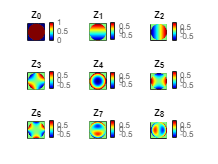

addpath(genpath('.\file_exchange'));

dx = 6.5e-6; %0.1e-6;   % pixel spacing (m)

xaxis = ((-len/2):(len/2-1))*dx;
yaxis = -xaxis;

num_mode = (n_mode+1)*(n_mode+2)/2;
p = (0:num_mode-1)';
z = zeros(size(X));
y = zernfun2(p,r(is_in),theta(is_in));

Zs = zeros(num_mode,len,len);
for k=1:num_mode
    z(is_in) = y(:,k);
    Zs(k,:,:) = z;
end


%% plot the zernike polynomials
for k = 1:9%length(p)
    z(is_in) = y(:,k);
    subplot(3,3,k)
    pcolor(xaxis,xaxis,z), shading interp
    colormap(jet);
    set(gca,'XTick',[],'YTick',[])
    axis square
    title(['Z_{' num2str(p(k)) '}'])
    colorbar;
    
    Zs(k,:,:) = z;
end

## Generate images with phase aberration

### Object image (USAF1951 target image)

Objimage = imread('usaf_1951.jpg'); % Object image : 800 x 618 x 3
Objimage = rgb2gray(Objimage); % rbg -> gray conversion
Obj = im2double(Objimage, 'indexed'); % convert unit8 to double (double-precision)

Obj = imresize(Obj, [len len]); % convert 800 x 800 to len x len
% Obj = ( Obj - min(min(Obj)) ) / max(max( ( Obj - min(min(Obj)) ) ));

fObj = fftshift(fft2(ifftshift(Obj))); % Object image -> frequency domain (FFT)

## Make input object

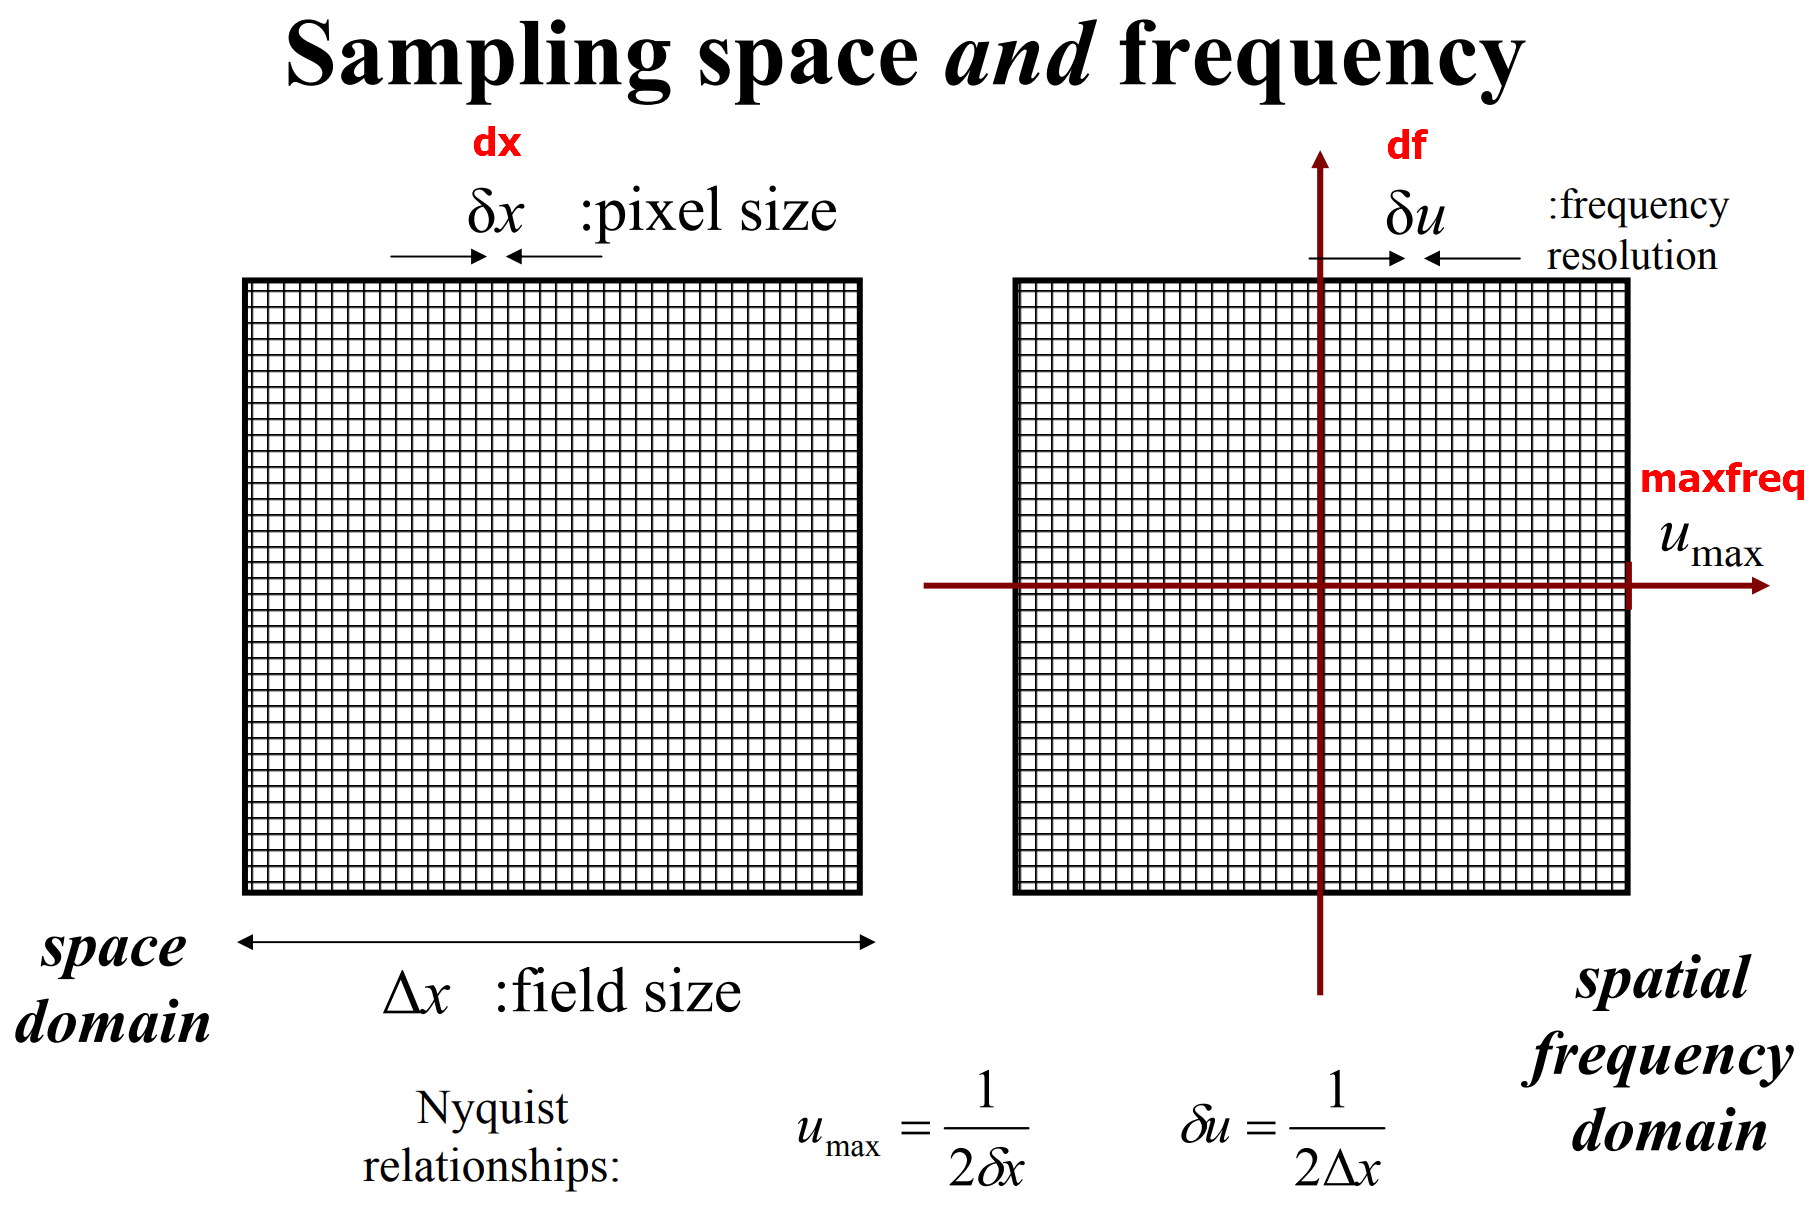

mag = 1;
res = len*mag; % resolution of FFT 
xaxis = ((-len/2):(len/2-1))*dx;
yaxis = -xaxis;

xaxis_res = ((-res/2):(res/2-1))*dx/mag;
yaxis_res = -xaxis_res;

[XX,YY] = meshgrid(xaxis,yaxis);  %2-D arrays hold x location and fy location of all points

## `Setup the simulation parameters`

wavelength = 532.0e-9;  % meter
rad = wavelength/(2*pi);
wavenumber = (2*pi)/wavelength;    % wavenumber (1/m)
NA = 1.3; % 0.5    % Numerical aperture of the objective
power = 0.1; % Watts
Z0 = 376.73; % Ohms; impedance of free space

###  Make pixel array for image plane and pupil plane

df = 1/(len*dx); % spacing in the spatial frequency domain (cycles/m)

fxaxis = ((-len/2):(len/2-1))*df;
fyaxis = -fxaxis;
[FX,FY] = meshgrid(fxaxis,fyaxis);  %2-D arrays hold fx location and fy location of all points
freq_rad = sqrt(FX.^2 + FY.^2);
maxfreq = (len/2-1)*df;

pupil_radius = 1.0*maxfreq; %NA / wavelength % 1.0*maxfreq; % radius of the pupil, inverse microns % (Hanser, 2004) doi.org/10.1111/j.0022-2720.2004.01393.x
pupil_area = pi*pupil_radius^2; % pupil area
pupil = double(freq_rad <= pupil_radius); % pin-hole
pupil_max = double(freq_rad <= maxfreq);

norm_factor = simps(fxaxis,simps(fxaxis,pupil.^2)) / Z0;
normalization_constant = norm_factor^0.5; % Watt

normedPupil = pupil.*(power/norm_factor)^0.5;
new_power = simps(fxaxis,simps(fxaxis,normedPupil.^2)) / Z0; % power in the pupil plane

pd_magnitude = 10; % magnitude of phase diversiy
pd_list = (-pd_magnitude:pd_magnitude:pd_magnitude); % [-10, 0, 10] means using minus, zero, plus values for defocus.

### Iteration : 입력 파면수차에 대한 feature intensity, f0 생성

1. 파면 수차

 - phase_valid : 고차 수차 성분을 모두 포함한 파면 수차 (piston, tip, tilt 제외)

 - phase_valid_Zernike : nx개의 Zernike mode로 구성된 파면 수차

2. nx : # of states → nx개의 Zernike mode로 구성된 파면 생성

3. input : phase_valid_Zernike

4. output : feature_intensity (f0)

nx = 8; % number of states
idx2 = 4; % index for defocus in OSA/ANSI standard index

ad_acc(:,1) = []; % piston mode is removed

reg_para = 1e-40*ones(nx,1); % regularization parameter to prevent oscillations by noise amplification
norm_para = 1e+15; % error metric (cost function) normalization parameter
T_final = size(phase,3);

ad_acc_valid = zeros(T_final,nx);
phase_valid = zeros(len,len,T_final);
phase_valid_Zernike = zeros(len,len,T_final);

% v_im_acc = zeros(len,len,length(pd_list),T_final);
% fv_im_acc = complex(zeros(len,len,length(pd_list),T_final));

% Imag_acc = zeros(len,len,length(pd_list),T_final);
% fImag_acc = complex(zeros(len,len,length(pd_list),T_final));

% P_defocus = complex(zeros(len,len,length(pd_list),T_final));
% I_defocus = complex(zeros(len,len,length(pd_list),T_final));

Out of memory.

Related documentation


for iSimStep=1:size(phase,3)
    tStart_iter = tic;
    %% Tip / Tilt compensation
    Zs_tip_tilt = zeros(2,len,len);
    for j1=1:2
        Zs_tip_tilt(j1,:,:) = ad_acc(iSimStep,j1).*squeeze(Zs(j1+1,:,:)); % piston element is removed
    end
    phase_tip_tilt = squeeze(sum(Zs_tip_tilt,1));

    ad_acc_valid(iSimStep,3:nx) = ad_acc(iSimStep,3:nx);
    phase_valid(:,:,iSimStep) = phase(:,:,iSimStep) - phase_tip_tilt;
    
    Zs_gen = zeros(nx,len,len);
    for j1=1:nx
        Zs_gen(j1,:,:) = ad_acc_valid(iSimStep,j1).*squeeze(Zs(j1+1,:,:));
    end
    phase_valid_Zernike(:,:,iSimStep) = squeeze(sum(Zs_gen,1));

    phase_valid_diff(:,:,iSimStep) = phase_valid(:,:,iSimStep) - phase_valid_Zernike(:,:,iSimStep);
    RMS_phase_diff(iSimStep,1) = sqrt(mean(mean( ( phase_valid_diff(:,:,iSimStep) ).^2 ))); % influence of high-order aberrations
    
    scrn = phase_valid_Zernike(:,:,iSimStep); % Phase screen used for our simulation // phase_valid_Zernike(:,:,iSimStep)

    % PSF & gradient generation
    for k=1:length(pd_list)
        kW = pd_list(k).*squeeze(Zs(idx2+1,:,:));
        P0_defocus = pupil.*exp(1i*(scrn + kW)); % DH-PSF (gaussian is removed)
        I0_defocus = fftshift(fft2(ifftshift(P0_defocus),res,res))*dx^2;

        im = abs(I0_defocus).^2;
        v_im(:,:,k) = im;
        fv_im(:,:,k) = fftshift(fft2(ifftshift(v_im(:,:,k))));

        for j2=3:nx
            P1_defocus = P0_defocus.*squeeze(Zs(j2+1,:,:)); % gradient of GPF
            I1_defocus = fftshift(fft2(ifftshift(P1_defocus)))*dx^2;
            fv_im_grad(:,:,k,j2) = fftshift(fft2(ifftshift( -2*imag(I1_defocus.*conj(I0_defocus)) ))); %
        end

        % Obtain FFT of Image intensity distribution (by inverse FFT)
        fImag(:,:,k) = fObj .* fv_im(:,:,k); % I = O*H
        Imag(:,:,k) = ifftshift(ifft2(fftshift(fImag(:,:,k)))); % i = iFFT(I)
    end

    feature_image(:,:,iSimStep) = fImag(:,:,3) ./ fImag(:,:,2); % feature image, f
    feature_intensity(:,:,iSimStep) = ifftshift(ifft2(fftshift( fImag(:,:,3) ./ fImag(:,:,2) ))); % feature intensity, f0

%     feature_image_grad(:,:,:,iSimStep) = feature_intensity_grad_cal(fv_im, fv_im_grad, nx, len);
    
%     v_im_acc(:,:,:,iSimStep) = v_im;
%     fv_im_acc(:,:,:,iSimStep) = fv_im;

%     fImag_acc(:,:,:,iSimStep) = fImag;
%     Imag_acc(:,:,:,iSimStep) = Imag;
    T_iter(iSimStep,1) = toc(tStart_iter);

    if rem(iSimStep,2000) == 0
        disp(iSimStep)
    end
end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% complex variable cart2pol %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% feature_image_r = zeros(len,len,size(phase,3));
% feature_image_theta = zeros(len,len,size(phase,3));
% 
% feature_image_grad_r = zeros(len,len,nx,size(phase,3));
% feature_image_grad_theta = zeros(len,len,nx,size(phase,3));z
% 
% [feature_image_theta, feature_image_r] = cart2pol(real(feature_image), imag(feature_image));
% % [fv_im_acc_theta, fv_im_acc_r] = cart2pol(real(fv_im_acc), imag(fv_im_acc));
% 
% for iSimStep=1:T_final
%     for i=1:nx
%         [feature_image_grad_theta(:,:,i,iSimStep), feature_image_grad_r(:,:,i,iSimStep)] = cart2pol(real(feature_image_grad(:,:,i,iSimStep)), imag(feature_image_grad(:,:,i,iSimStep)));
%     end
% end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

norm_ad = []; rms_phase = [];
for i=1:size(ad_acc_valid,1)
    norm_ad(i,1) = norm(ad_acc_valid(i,:));
    rms_phase(i,1) = sqrt(mean( mean( abs(phase_valid_Zernike(:,:,i)).^2 ) ));
end

savename = sprintf('./data_result/data_len%d.mat',len);
save(savename,'ad_acc_valid','r0','norm_ad','rms_phase','feature_intensity', 'phase_valid_Zernike')




## Figure plot (.gif)

### *1. Phase aberration*

h = figure('Visible','off','Position',[0 0 1500 500]);
subplot(1,3,1)
pcolor(xaxis,xaxis,scrn-3*squeeze(Zs(5,:,:))), shading interp % scrn → phase_valid(:,:,iSimStep)
colorbar;
set(gca,'FontSize',15,'XTick',[],'YTick',[])
axis square
% caxis([-6 6])
title('Phase aberration with minus defocus')

subplot(1,3,2)
pcolor(xaxis,xaxis,scrn), shading interp % scrn → phase_valid(:,:,iSimStep)
colorbar;
set(gca,'FontSize',15,'XTick',[],'YTick',[])
axis square
% caxis([-6 6])
title('Phase aberration')
% set(gca,'FontSize',13,'XTick',[],'YTick',[])
movegui(h,'center'), set(h,'Visible','on')

subplot(1,3,3)
pcolor(xaxis,xaxis,scrn+3*squeeze(Zs(5,:,:))), shading interp % scrn → phase_valid(:,:,iSimStep)
colorbar;
set(gca,'FontSize',15,'XTick',[],'YTick',[])
axis square
% caxis([-6 6])
title('Phase aberration with plus defocus')
% set(gca,'FontSize',13,'XTick',[],'YTick',[])
movegui(h,'center'), set(h,'Visible','on')




% figure(12)
% video = VideoWriter('phase.mp4', 'MPEG-4');
% open(video)
% for t = 1:size(phase_valid_Zernike,3)
%     pcolor(xaxis,xaxis,phase_valid_Zernike(:,:,t)), shading interp
%     frame = getframe(gcf);
%     title(strcat('Phase aberration when k= ', num2str(t)))
%     colorbar;
%     caxis([-1 1])
%     set(gca,'FontSize',13,'XTick',[],'YTick',[])
%     writeVideo(video, frame)
%     for j = 1:3 % 1초당 30 frame이므로 이미지 1장당 3/30초가 걸리도록 설정
%         writeVideo(video, frame);
%     end
% end
% close(video)





### *2. Feature intensity (f_0) plot*

figure(8)
pcolor((1:len),(1:len),feature_intensity(:,:,iSimStep)), shading interp
colorbar;
% caxis([-3 3])
title('$$\mathbf{f_0} = \left| \mathcal{F}^{-1} \left\{ \mathcal{F}\{i_{+d}(\mathbf{v})\} / \mathcal{F}\{i_{0}(\mathbf{v})\} \right\} \right|$$','Interpreter','Latex')
set(gca,'FontSize',15) %,'XTick',[],'YTick',[])

% 
% figure(12)
% video = VideoWriter('feature_intensity.mp4', 'MPEG-4');
% open(video)
% for t = 1:size(feature_intensity,3)
%     pcolor(xaxis,xaxis,feature_intensity(:,:,t)), shading interp
%     frame = getframe(gcf);
%     title(strcat('Phase aberration when k= ', num2str(t)))
%     colorbar;
%     caxis([-1 1])
%     set(gca,'FontSize',13,'XTick',[],'YTick',[])
%     writeVideo(video, frame)
%     for j = 1:3 % 1초당 30 frame이므로 이미지 1장당 3/30초가 걸리도록 설정
%         writeVideo(video, frame);
%     end
% end
% movegui(h,'center'), set(h,'Visible','on')
% close(video) 







## Error metric calculation (PDBD-new)

function E_metric = error_metric_cal_v2(Zs, pd_list, pupil, idx2, dx, reg_para, norm_para, fImag) % phase_var, Zs, zd_list, pupil, idx2, dx
    for k=1:length(pd_list)
        kW = pd_list(k).*squeeze(Zs(idx2+1,:,:));
        P_defocus = pupil.*exp(1i*(kW)); % zero-aberration
        I_defocus = fftshift(fft2(ifftshift(P_defocus)))*dx^2;
        v_im(:,:,k) = abs(I_defocus).^2;
        fv_im(:,:,k) = fftshift(fft2(ifftshift(v_im(:,:,k))));
    end
    
    % E_metric size : len x len ( remove sum(sum( ... )))
    E_metric = norm_para*0.5*(  abs( fImag(:,:,1).*fv_im(:,:,3) - fImag(:,:,3).*fv_im(:,:,1) ).^2 ...
                                       + abs( fImag(:,:,1).*fv_im(:,:,2) - fImag(:,:,2).*fv_im(:,:,1) ).^2 ...
                                        + abs( fImag(:,:,2).*fv_im(:,:,3) - fImag(:,:,3).*fv_im(:,:,2) ).^2 ...
                                        + reg_para(1,1)*( abs(fImag(:,:,1)).^2 + abs(fImag(:,:,2)).^2 + abs(fImag(:,:,3)).^2 )  ) ...
                                  ./ (  abs( fv_im(:,:,1) ).^2 + abs( fv_im(:,:,2) ).^2 + abs( fv_im(:,:,3) ).^2 + reg_para(1,1) ); % ...

end

## Feature image gradient calculation

function feature_intensity_grad = feature_intensity_grad_cal(fv_im, fv_im_grad, nx, len) % phase_var, Zs, zd_list, pupil, idx2, dx
    
    feature_intensity_grad = zeros(len,len,nx);

    % data pre-calculation
    denom = ( fv_im(:,:,2) ).^2;

    for iter=3:nx
        numer1 = fv_im_grad(:,:,3,iter) .* fv_im(:,:,2);
        numer2 = fv_im_grad(:,:,2,iter) .* fv_im(:,:,3);
        
        % feature_image_grad size : len x len x nx 
        feature_intensity_grad(:,:,iter) = (numer1 - numer2) ./ denom;
    end
end

## Simpson's numerical integration

function z = simps(x,y,dim)
%SIMPS  Simpson's numerical integration.
%   The Simpson's rule for integration uses parabolic arcs instead of the
%   straight lines used in the trapezoidal rule.
%
%   Z = SIMPS(Y) computes an approximation of the integral of Y via the
%   Simpson's method (with unit spacing). To compute the integral for
%   spacing different from one, multiply Z by the spacing increment.
%29
%   For vectors, SIMPS(Y) is the integral of Y. For matrices, SIMPS(Y) is a
%   row vector with the integral over each column. For N-D arrays, SIMPS(Y)
%   works across the first non-singleton dimension.
%
%   Z = SIMPS(X,Y) computes the integral of Y with respect to X using the
%   Simpson's rule. X and Y must be vectors of the same length, or X must
%   be a column vector and Y an array whose first non-singleton dimension
%   is length(X). SIMPS operates along this dimension.
%
%   Z = SIMPS(X,Y,DIM) or SIMPS(Y,DIM) integrates across dimension DIM of
%   Y. The length of X must be the same as size(Y,DIM).
%
%   Examples:
%   --------
%   % The integration of sin(x) on [0,pi] is 2
%   % Let us compare TRAPZ and SIMPS
%   x = linspace(0,pi,6);
%   y = sin(x);
%   trapz(x,y) % returns 1.9338 
%   simps(x,y) % returns 2.0071
%
%   If Y = [0 1 2
%           3 4 5
%           6 7 8]
%   then simps(Y,1) is [6 8 10] and simps(Y,2) is [2; 8; 14]
%
%   -- Damien Garcia -- 08/2007, revised 11/2009
%   website: <a
%   href="matlab:web('http://www.biomecardio.com')">www.BiomeCardio.com</a>
%
%   See also CUMSIMPS, TRAPZ, QUAD.
%   Adapted from TRAPZ
%--   Make sure x and y are column vectors, or y is a matrix.
perm = []; nshifts = 0;
if nargin == 3 % simps(x,y,dim)
  perm = [dim:max(ndims(y),dim) 1:dim-1];
  yp = permute(y,perm);
  [m,n] = size(yp);
elseif nargin==2 && isscalar(y) % simps(y,dim)
  dim = y; y = x;
  perm = [dim:max(ndims(y),dim) 1:dim-1];
  yp = permute(y,perm);
  [m,n] = size(yp);
  x = 1:m;
else % simps(y) or simps(x,y)
  if nargin < 2, y = x; end
  [yp,nshifts] = shiftdim(y);
  [m,n] = size(yp);
  if nargin < 2, x = 1:m; end
end
x = x(:);
if length(x) ~= m
  if isempty(perm) % dim argument not given
    error('MATLAB:simps:LengthXmismatchY',...
          'LENGTH(X) must equal the length of the first non-singleton dimension of Y.');
  else
    error('MATLAB:simps:LengthXmismatchY',...
          'LENGTH(X) must equal the length of the DIM''th dimension of Y.');
  end
end
%-- The output size for [] is a special case when DIM is not given.
if isempty(perm) && isequal(y,[])
  z = zeros(1,class(y));
  returns
end
%-- Use TRAPZ if m<3
if m<3
    if exist('dim','var')
        z = trapz(x,y,dim);
    else
        z = trapz(x,y);
    end
    return
end
%-- Simpson's rule
y = yp;
clear yp
dx = repmat(diff(x,1,1),1,n);
dx1 = dx(1:end-1,:);
dx2 = dx(2:end,:);
alpha = (dx1+dx2)./dx1/6;
a0 = alpha.*(2*dx1-dx2);
a1 = alpha.*(dx1+dx2).^2./dx2;
a2 = alpha.*dx1./dx2.*(2*dx2-dx1);
z = sum(a0(1:2:end,:).*y(1:2:m-2,:) +...
    a1(1:2:end,:).*y(2:2:m-1,:) +...
    a2(1:2:end,:).*y(3:2:m,:),1);
if rem(m,2) == 0 % Adjusting if length(x) is even   
    state0 = warning('query','MATLAB:nearlySingularMatrix');
    state0 = state0.state;
    warning('off','MATLAB:nearlySingularMatrix')
    C = vander(x(end-2:end))\y(end-2:end,:);
    z = z + C(1,:).*(x(end,:).^3-x(end-1,:).^3)/3 +...
        C(2,:).*(x(end,:).^2-x(end-1,:).^2)/2 +...
        C(3,:).*dx(end,:);
    warning(state0,'MATLAB:nearlySingularMatrix')
end
%-- Resizing
siz = size(y); siz(1) = 1;
z = reshape(z,[ones(1,nshifts),siz]);
if ~isempty(perm), z = ipermute(z,perm); end
end







